# EE512 - Aplied Biomedical signal Processing

# Practical Session Moule07-Instantaneous Frequency Estimation

# Adrian Luca

#### Students:

Vincent Roduit

Fabio Palmisano

Caspar Henking

Bastien Marconato

Seif Labib

## Experiment 1

### IF estimation form surface ECG during atrial fibrillation

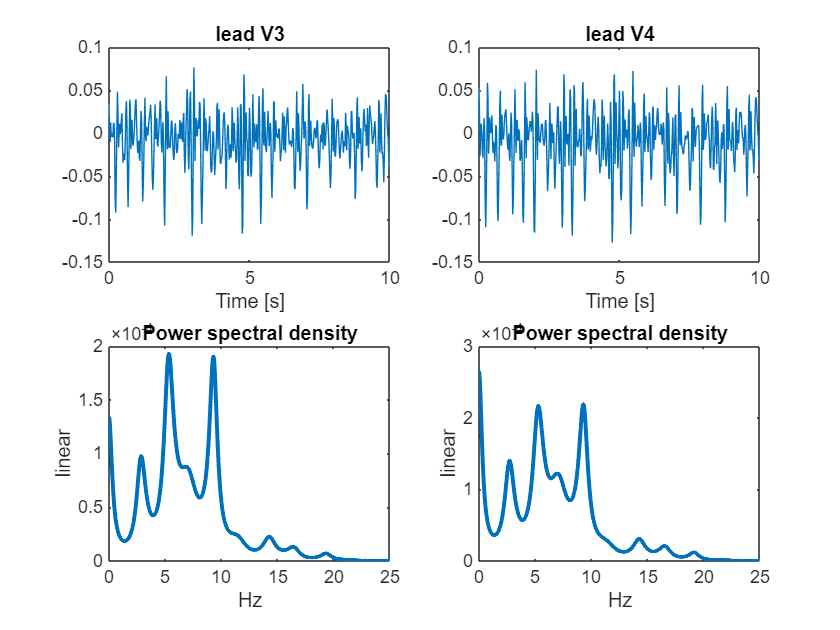

close all
clear all
AA = load('AA_AFib.dat');

V3 = AA(:,9);
V4 = AA(:,10);

N = size(AA,1);
Fs = 50;

%visualize the raw signals and their PSD estimates

figure
t = (0:N-1)./Fs;
subplot(221), plot(t, V3), title('lead V3'), xlabel('Time [s]')
subplot(223), AR_psd(V3, 20, 50, 25, 0, 1);
set(gcf, 'Name', 'raw V3 signal and the PSD')


subplot(222), plot(t, V4), title('lead V4'), xlabel('Time [s]')
subplot(224), AR_psd(V4, 20, 50, 25, 0, 1);
set(gcf, 'Name', 'raw V4 signal and the PSD')

%design the IIR bandpass filter [4-7]Hz
[Nb,wn] =buttord([0.16 0.28], [0.12 0.32],0.5,20);
[b,a] = butter(Nb,wn);

#### Q1.1.    Is the frequency response of the filter adequate ?

***Answer: ***Yes, the pass-band of the filter corresponds to the frequency range of atrial fibrillation usually met in clinical practice (4-7 Hz). These frequencies can be observed as peaks in power spectral density (one peak at 5Hz and the other one at 9Hz).

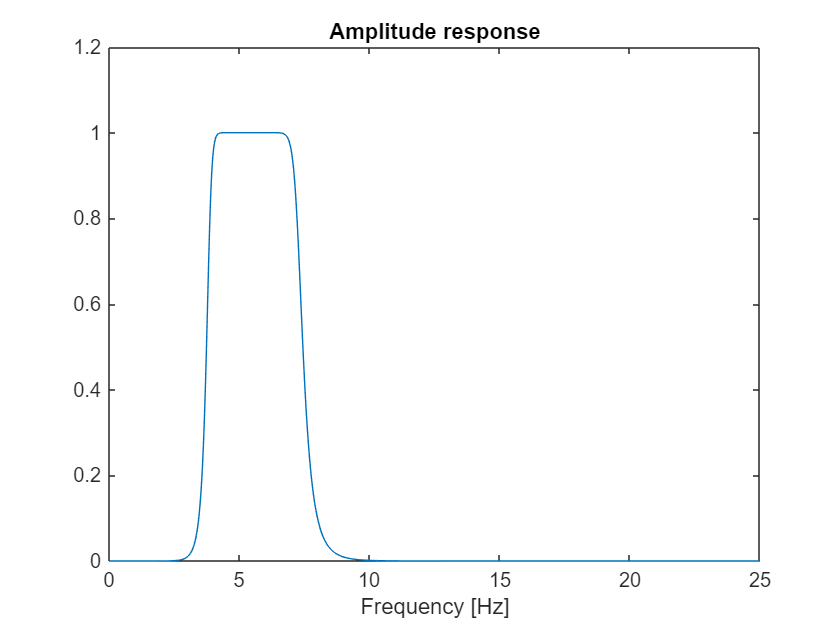

%visualize the filter
% Fig. 3
figure
[h,w]=freqz(b,a,1000);
plot(Fs*linspace(0,0.5,1000),abs(h)), title('Amplitude response'), xlabel('Frequency [Hz]')
set(gcf, 'Name', 'Amplitude response of the bandpass filter')

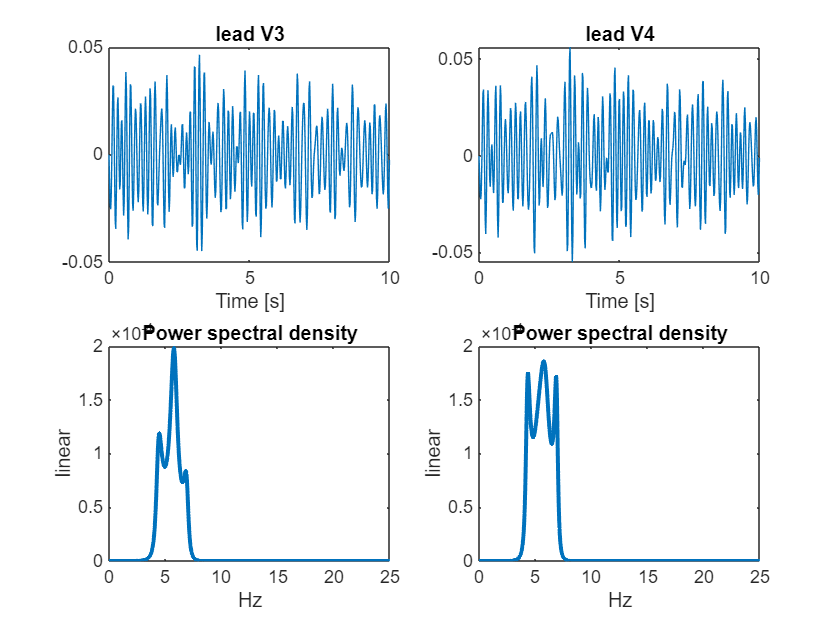

%filter the signals
V3_filt = filtfilt(b,a,V3);
V4_filt = filtfilt(b,a,V4);

%visualize the filtered signals and their PSD estimates
figure
subplot(221), plot(t, V3_filt), title('lead V3'), xlabel('Time [s]')
subplot(223), AR_psd(V3_filt, 20, 50, 25, 0, 1);
set(gcf, 'Name', 'filtered V3 signal and the PSD')


subplot(222), plot(t, V4_filt), title('lead V4'), xlabel('Time [s]')
subplot(224), AR_psd(V4_filt, 20, 50, 25, 0, 1);
set(gcf, 'Name', 'filtered V4 signal and the PSD')

#### Q1.2.    The maximum frequency for the plot is set at 25Hz. Why wouldn't it make sense to visualize a spectrum of higher frequencies?

***Answer: ***Because the sampling frequency is 50Hz. By Nyquist-Shannon's theorem, this sampling frequency only allows the reconstruction of signals of up to 50/2 = 25 Hz.

% IF estimation on raw signals
IF_STFT = STFT(V3,31,50);

For a faster computation, N should be a power of two


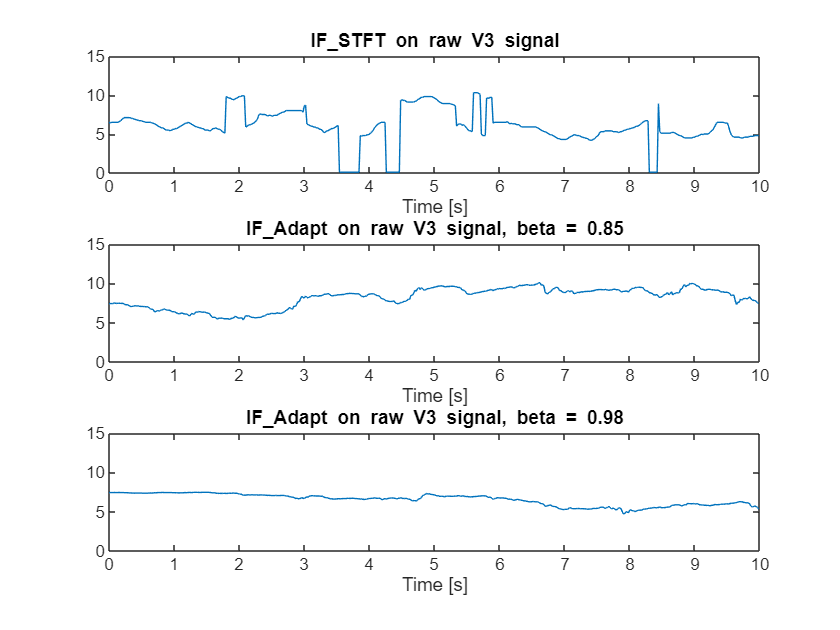

[IF_Adapt_1,y] = AdaptBP(V3,5,0.85,0.9,50,0);
[IF_Adapt_2,y] = AdaptBP(V3,5,0.98,0.9,50,0);
figure
subplot(311), plot(t, IF_STFT), title('IF\_STFT on raw V3 signal'), xlabel('Time [s]'), ylim([0 15])
subplot(312), plot(t, IF_Adapt_1), title('IF\_Adapt on raw V3 signal, beta = 0.85'), xlabel('Time [s]'), ylim([0 15])
subplot(313), plot(t, IF_Adapt_2), title('IF\_Adapt on raw V3 signal, beta = 0.98'), xlabel('Time [s]'), ylim([0 15])
set(gcf, 'Name', 'IF estimation on raw V3 signal')

IF_STFT = STFT(V4,31,50);

For a faster computation, N should be a power of two


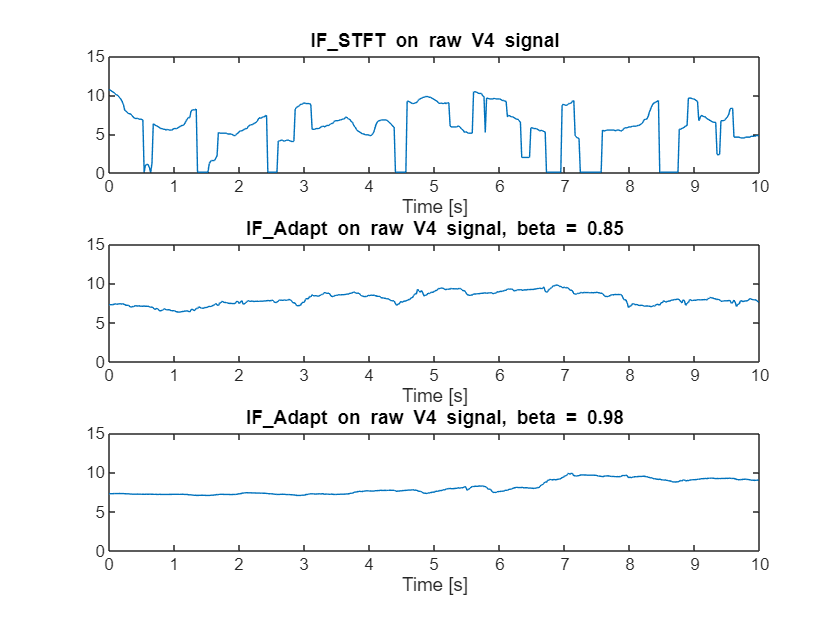

[IF_Adapt_1, y] = AdaptBP(V4,5,0.85,0.9,50,0);
[IF_Adapt_2, y] = AdaptBP(V4,5,0.98,0.9,50,0);
figure
subplot(311), plot(t, IF_STFT), title('IF\_STFT on raw V4 signal'), xlabel('Time [s]'), ylim([0 15])
subplot(312), plot(t, IF_Adapt_1), title('IF\_Adapt on raw V4 signal, beta = 0.85'), xlabel('Time [s]'), ylim([0 15])
subplot(313), plot(t, IF_Adapt_2), title('IF\_Adapt on raw V4 signal, beta = 0.98'), xlabel('Time [s]'), ylim([0 15])
set(gcf, 'Name', 'IF estimation on raw V4 signal')


% IF estimation on filtered signals
IF_STFT = STFT(V3_filt,31,50);

For a faster computation, N should be a power of two


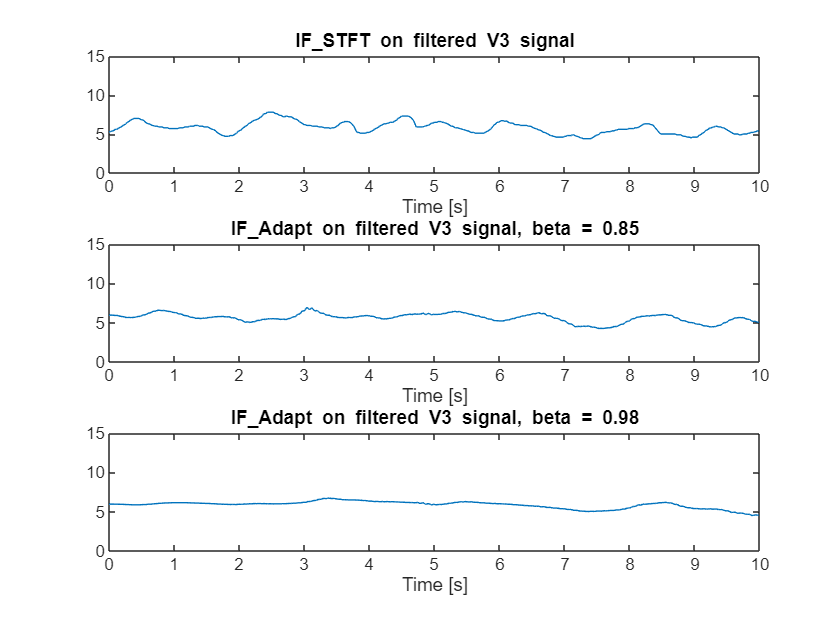

[IF_Adapt_1f,y] = AdaptBP(V3_filt,5,0.85,0.9,50,0);
[IF_Adapt_2f,y] = AdaptBP(V3_filt,5,0.98,0.9,50,0);
figure
subplot(311), plot(t, IF_STFT), title('IF\_STFT on filtered V3 signal'), xlabel('Time [s]'), ylim([0 15])
subplot(312), plot(t, IF_Adapt_1f), title('IF\_Adapt on filtered V3 signal, beta = 0.85'), xlabel('Time [s]'), ylim([0 15])
subplot(313), plot(t, IF_Adapt_2f), title('IF\_Adapt on filtered V3 signal, beta = 0.98'), xlabel('Time [s]'), ylim([0 15])
set(gcf, 'Name', 'IF estimation on filtered V3 signal')


IF_STFT = STFT(V4_filt,31,50);

For a faster computation, N should be a power of two


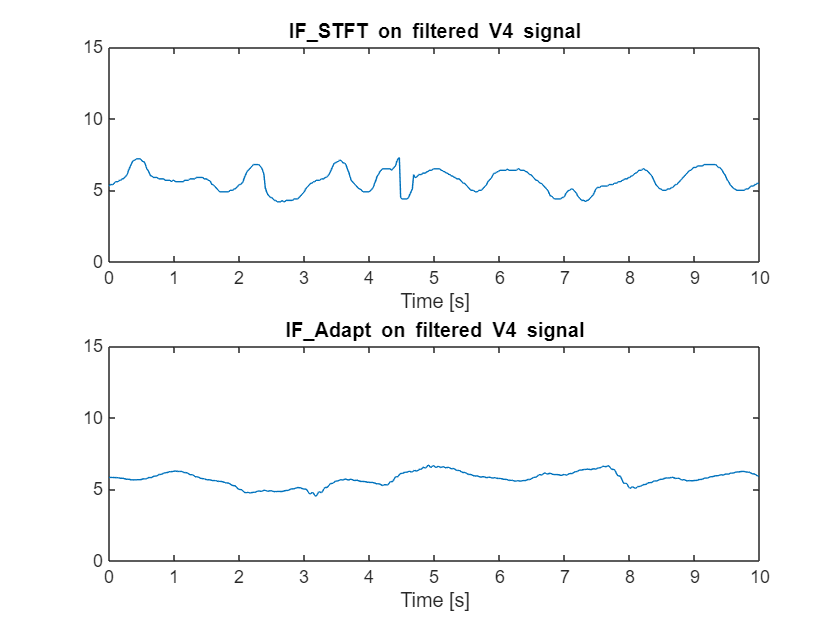

[IF_Adapt,y] = AdaptBP(V4_filt,4,0.95,0.9,50,0);
figure
subplot(211), plot(t, IF_STFT), title('IF\_STFT on filtered V4 signal'), xlabel('Time [s]'), ylim([0 15])
subplot(212), plot(t, IF_Adapt), title('IF\_Adapt on filtered V4 signal'), xlabel('Time [s]'), ylim([0 15])
set(gcf, 'Name', 'IF estimation on filtered V4 signal')

#### Q1.3.    Conclusion? Which method is the most effective? Was the bandpass pre-filtering worth it? How does the beta coefficient affect the IF estimation? Why?

The IF_adapt method produces a much more consistent estimation of the instantaneous frequency compared to the STFT, particularly on raw signals where the result of the STFT method features frequent sharp jumps.

The band-pass pre-filtering improves the smoothness of the estimated IF for both methods.

An increase in beta also result in a smoothed estimation of the instantaneous frequency, because the filter has a narrower filter bandwidth.

## Experiment 2

### estimation of respiration frequency from respiration sinus arrhythmia during a VO2-max test

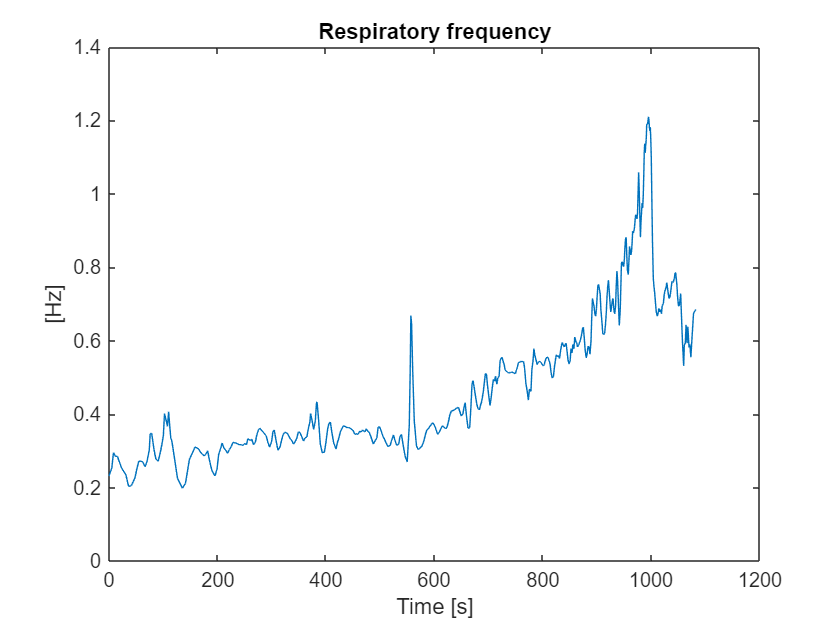

close all
clear all
load('VO2max.mat')

%visualize the signals
figure, plot(tr, RF), title('Respiratory frequency'), ylabel('[Hz]'), xlabel('Time [s]')

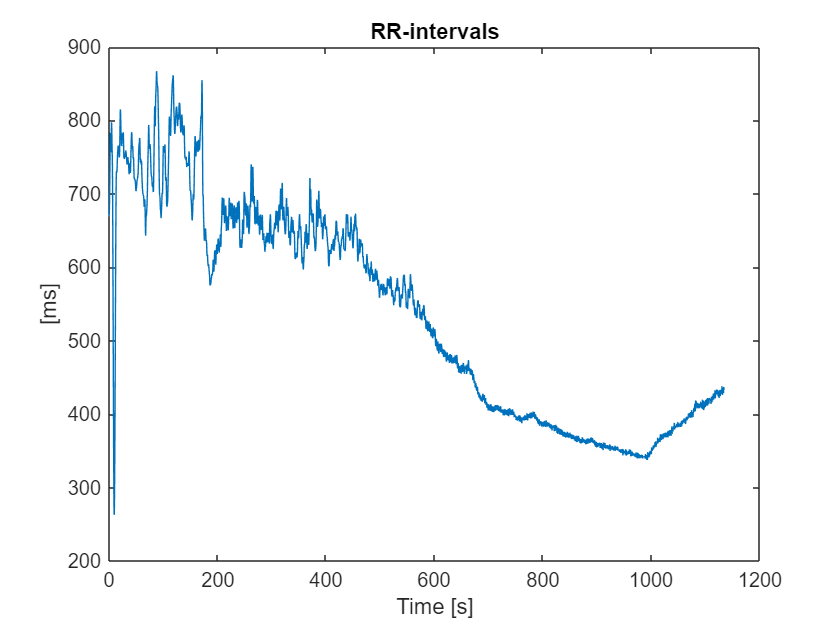

figure, plot(t, RR), title('RR-intervals'), ylabel('[ms]'), xlabel('Time [s]')

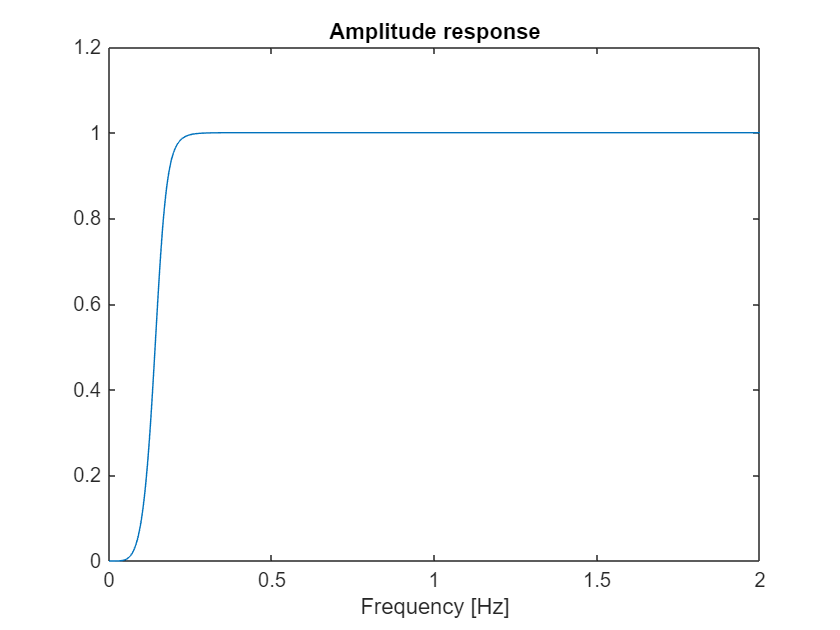

% high-pass IIR filter to remove the low-frequency components (<0.15Hz) in the RR signal
[N,Wn] = buttord(0.4/4,0.2/4,0.5,20) ;
[b,a] = butter(N,Wn,'high') ;
figure
[h,w]=freqz(b,a,1000);
plot(4.*linspace(0,0.5,1000),abs(h)), title('Amplitude response'), xlabel('Frequency [Hz]')
set(gcf, 'Name', 'Amplitude response of the high-pass filter')

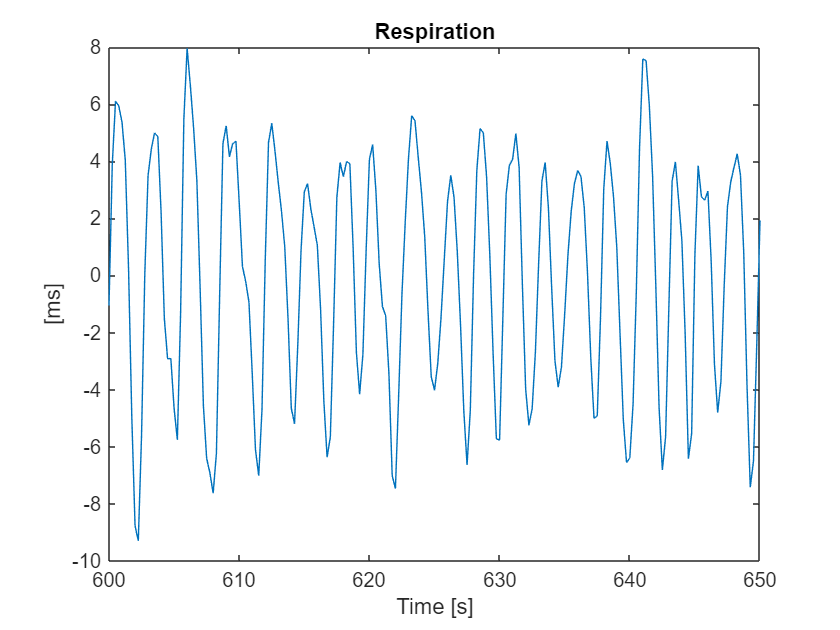

% extract the respiration component from the RR-intervals
Resp = filtfilt(b,a,RR-RR(1));
figure, plot(t, Resp), title('Respiration'), ylabel('[ms]'), xlabel('Time [s]'), xlim([600,650])

#### Q2.1.    Check that the output signal represent the respiration component only.

***Answer: *** As we can see on the zoomed signal, there is a clear dominating frequency that indicates the respiratory frequency, as there are approximatively four peaks every 10 seconds, which corresponds to a frequency of 0.4 Hz. This seems quite appropriate for a respiratory frequency.

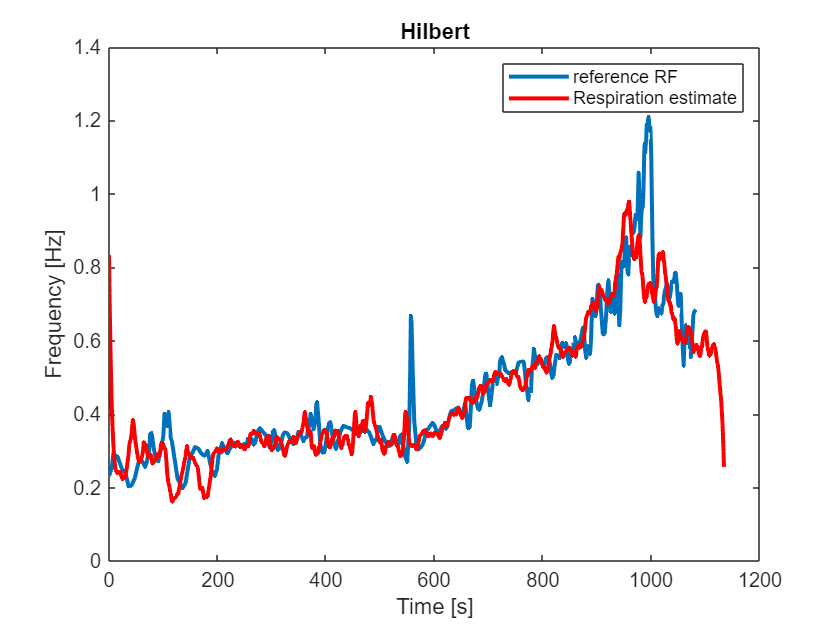

%IF estimation using Hilbert transform
figure
IF = IFhilbert(Resp,4);
a=0.05;
IFf = filtfilt(a,[1 a-1],IF);
plot(tr,RF,t,IFf,'r','LineWidth',2), legend('reference RF', 'Respiration estimate')
title('Hilbert')
set(gcf, 'Name', 'RF estimation using Hilbert transform')
xlabel('Time [s]')
ylabel('Frequency [Hz]')

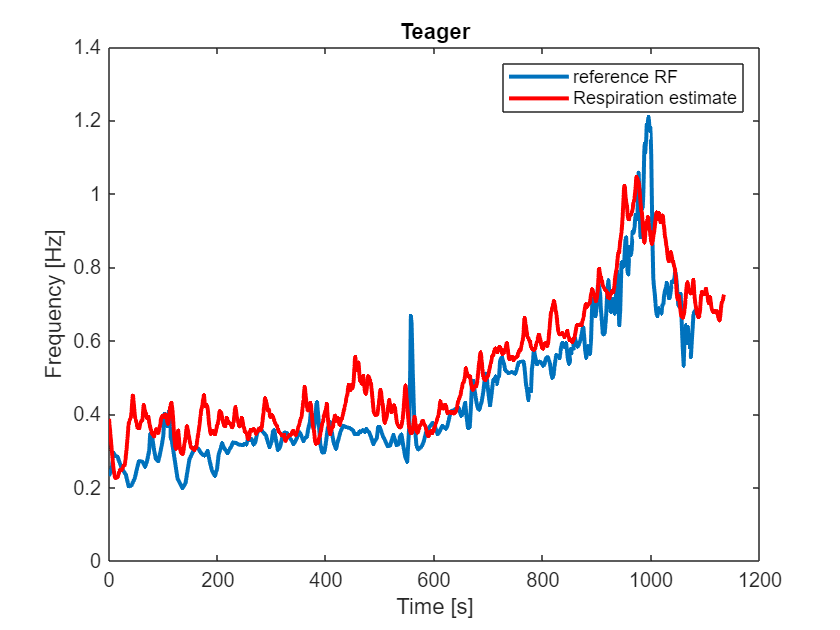

%IF estimation using Teager energy operator
figure
[IF,env] = teager(Resp,4);
a=0.05;
IFf = filtfilt(a,[1 a-1],IF);
plot(tr,RF,t,IFf,'r','LineWidth',2), legend('reference RF', 'Respiration estimate')
title('Teager')
set(gcf, 'Name', 'RF estimation using Teager energy operator')
xlabel('Time [s]')
ylabel('Frequency [Hz]')

%IF estimation using STFT
figure
IF = STFT(Resp, 31, 4);

For a faster computation, N should be a power of two


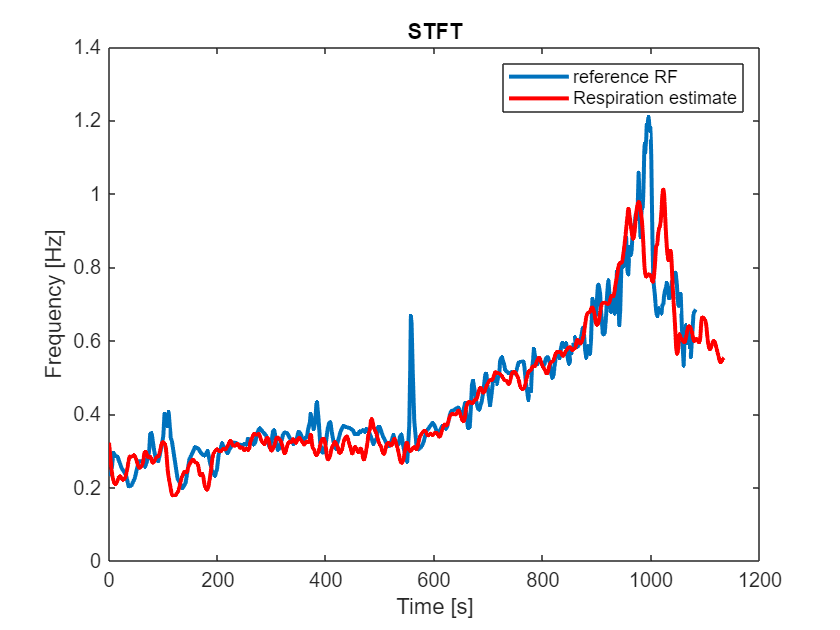

a=0.05;
IFf = filtfilt(a,[1 a-1],IF);
plot(tr,RF,t,IFf,'r','LineWidth',2), legend('reference RF', 'Respiration estimate')
title('STFT')
set(gcf, 'Name', 'RF estimation using STFT')
xlabel('Time [s]')
ylabel('Frequency [Hz]')

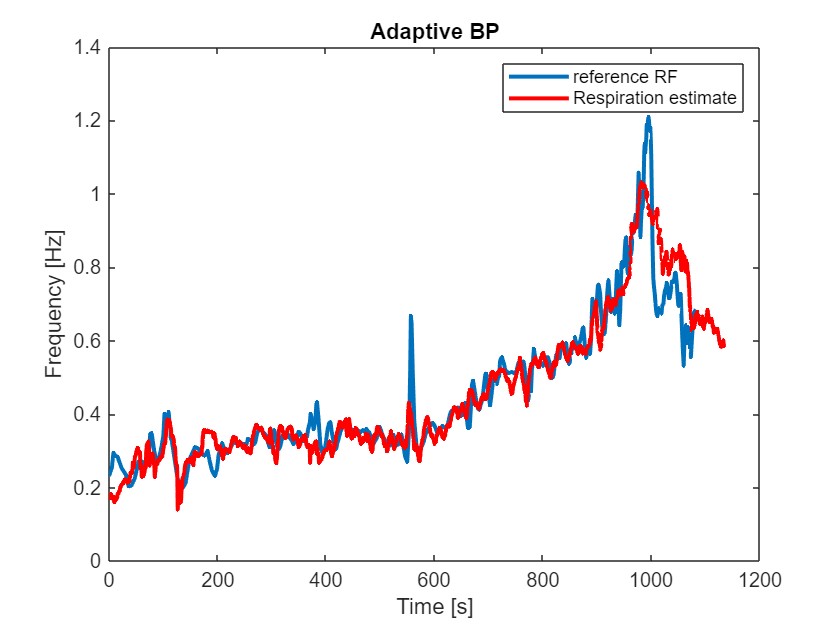

%IF estimation using adaptative IF tracking
%The best estimate seems to be obtained with the adaptive bandpass filter 
%(note that no lowpass filtering of the estimate is needed).
figure
[IF, y] = AdaptBP(Resp,0.25,0.925,0.925,4,0);
plot(tr,RF,t,IF,'r','LineWidth',2), legend('reference RF', 'Respiration estimate')
title('Adaptive BP')
set(gcf, 'Name', 'RF estimation using adaptative IF tracking')
xlabel('Time [s]')
ylabel('Frequency [Hz]')

#### Q2.2.    Assess the performances by visually comparing the IF estimate wiht the reference respiration frequency.

***Answer: ***Visually, the IF estimate is best with the adaptive method. It tracks the respiration frequency well, except at the beginning or when the changes are too sharp (just before 600 seconds and around 1000 seconds). However, these abrupt changes are not well handled by the other methods either.

## Experiment 3

### extraction of a common oscillation and estimation of its instantaneous frequency using bandpass adaptive filtering

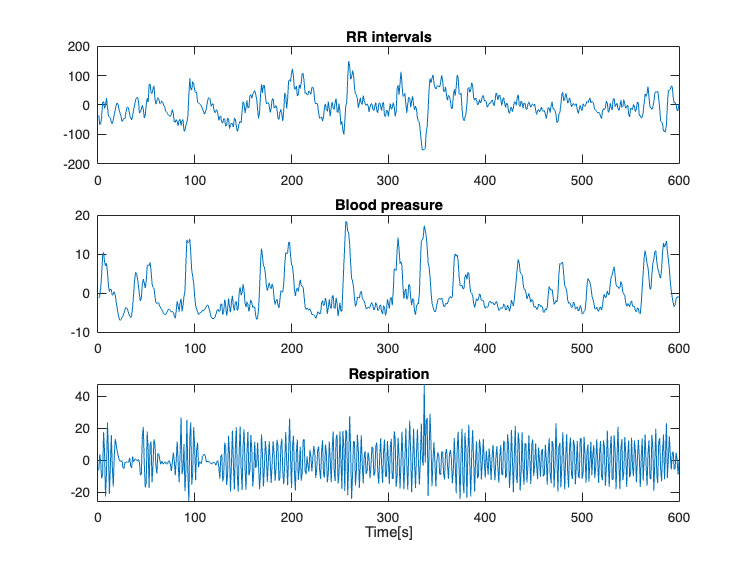

close all
clear all
load('heart_3.dat');

X = heart_3;
X = X - ones(length(X), 1) * mean(X);
X = resample(X,1,4);

RR = X(:,1);
BP = X(:,2);
Resp = X(:,3);

% %remove the mean and resample at 1Hz
% 
%  RR = resample(RR-mean(RR), 1, 4);
%  BP = resample(BP-mean(BP), 1, 4);
%  Resp = resample(Resp-mean(Resp), 1, 4);

% RR = RR-mean(RR);
% BP = BP-mean(BP);
% Resp = Resp-mean(Resp);

%visualize the signals
figure
subplot(311), plot(RR), title('RR intervals')
subplot(312), plot(BP), title('Blood preasure')
subplot(313), plot(Resp), title('Respiration'), xlabel('Time[s]')

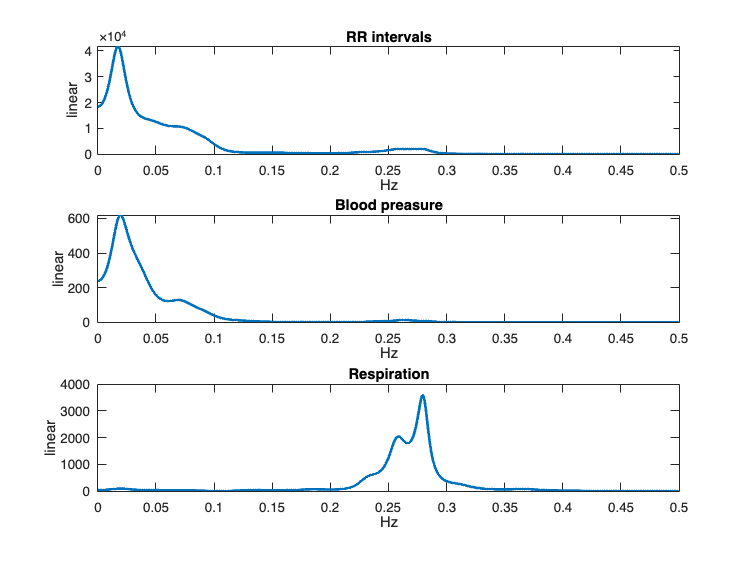

%power spectral densities
figure
subplot(311), [Px, freq] = AR_psd(RR, 30, 1, 0.5, 0, 1); title('RR intervals')
subplot(312), [Px, freq] = AR_psd(BP, 30, 1, 0.5, 0, 1); title('Blood preasure')
subplot(313), [Px, freq] = AR_psd(Resp,30, 1, 0.5, 0, 1); title('Respiration')

#### Q3.1.    Why were the signals downsampled from 4Hz to 1Hz ?

***Answer: ***The signal were downsampled by a factor of 4 in order to focus on lower frequencies. In fact, it can be seen the the frequencies of interests for RR and Blood pressure are located at very low frequencies (below 0.05Hz).

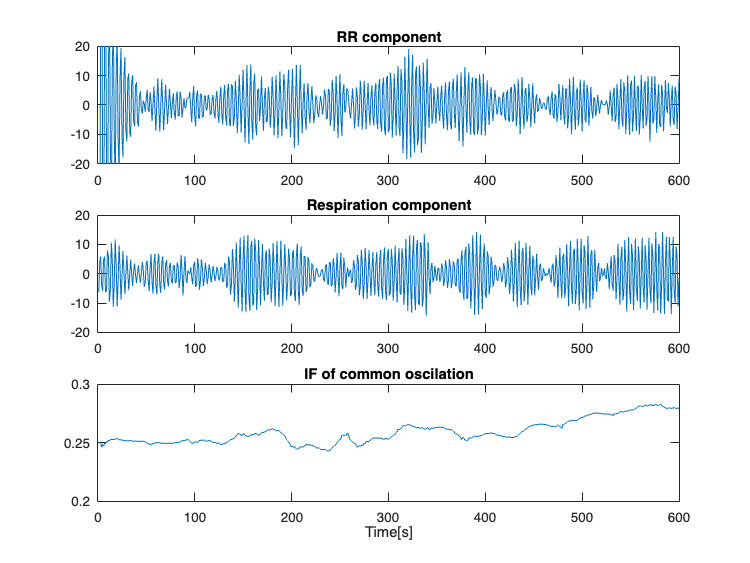

%extract the common oscillation between RR intervals and respiration.
% !!! the common oscilation is the respiration itself
[IF,Y,weights] = AdaptBP_weight([RR Resp],0.25,0.9,0.95,0.95,1);
figure
subplot(311), plot(Y(:,1)), title('RR component'), ylim([-20 20])
subplot(312), plot(Y(:,2)), title('Respiration component')
subplot(313), plot(IF), title('IF of common oscilation'), ylim([0.2, 0.3]), xlabel('Time[s]')

#### Q3.2.    What do the two filter outputs represent? Check visually that the amplitude of the two filter outputs are well correlated. What does the estimated IF represent? Compare the variation of the IF estimate with a non-parametric spectrum estimate of the respiration signal. 

***Answer:  ***The two filter outputs represent the common oscillation between RR and the respiration, which is the respiration itself. It can be visually seen that the amplitude of the two first plots matches well, except at the beginning. The estimated IF represents the respiration frequency. We can note that this frequency is not constant over time. Therefore, the use of a static method will to be reliable. 

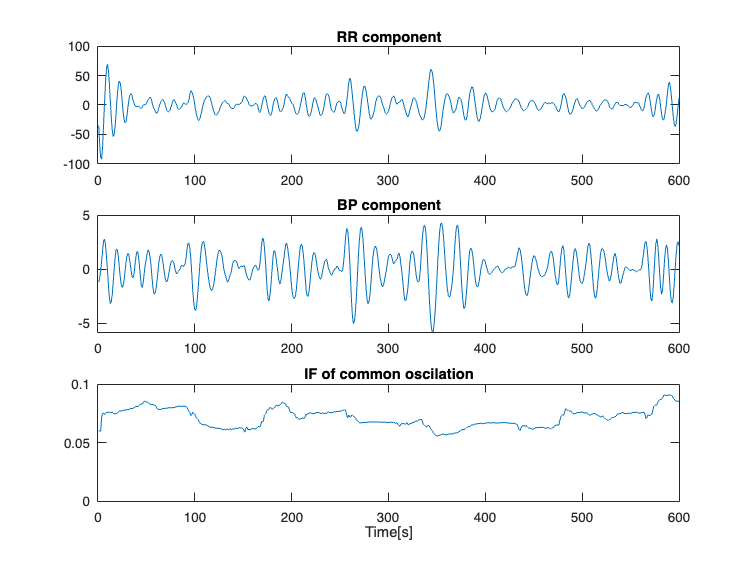

%extract the common oscillation between RR intervals and blood pressure
% !!! the common oscilation is the baroreflex
[IF,Y,weights] = AdaptBP_weight([RR BP],0.06,0.9,0.95,0.95,1);
figure
subplot(311), plot(Y(:,1)), title('RR component')
subplot(312), plot(Y(:,2)), title('BP component')
subplot(313), plot(IF), 
title('IF of common oscilation'), ylim([0, 0.1]), xlabel('Time[s]')

#### Q3.3.    What do the two filter outputs represent? Are the amplitudes of the two filter outputs correlated?

***Answer:  ***The two outputs represent the output of the common filter (for both RR and BP component). We can observe that there is an amplitude corellation between these two signals. This correlation is stronger in the large ampitude regions (around 280 and 350). Furthermore, IF of common oscillation shows the frequency of the baroreflex. It can be seen that the baroreflex has a frequency varying between 0.05 and ~0.8.